# Visión por Computador - Sesión 1

       Ferran Velasco Olivera

       Joaquín Gómez Sánchez

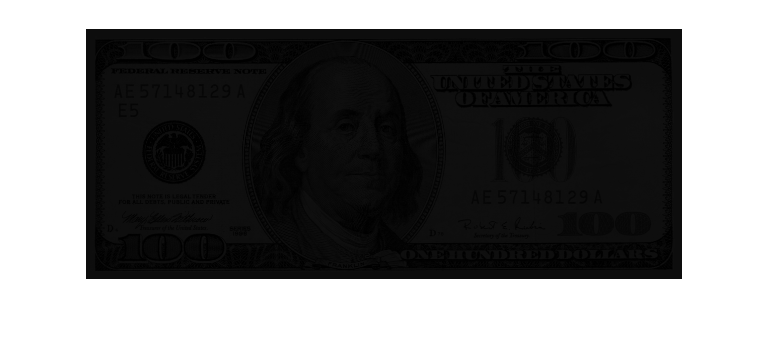

im = imread('Que_es.png');
imshow(im)

### Subir el brillo de una imagen

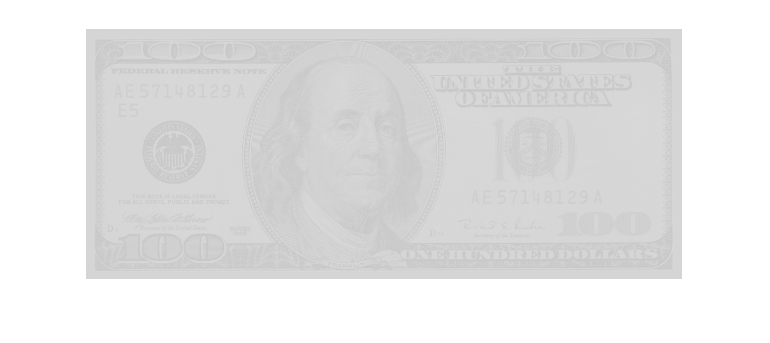

im2 = im + 200;
figure, imshow(im2)

### Subir el contraste de una imagen

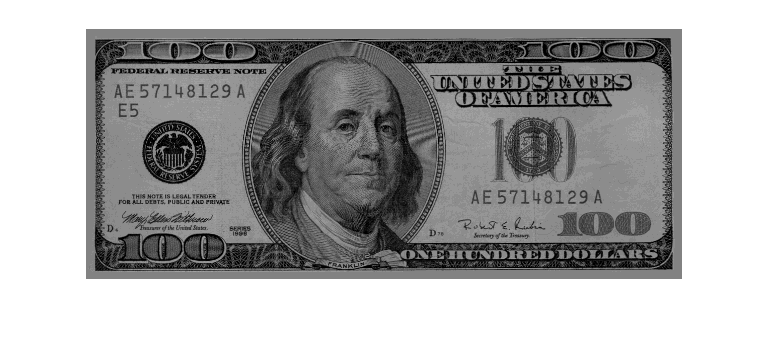

im3 = im * 10;
figure, imshow(im3)

### Construccion del histograma píxel a píxel

h = zeros(256, 1);
[files cols] = size(im)

files = 250

cols = 596

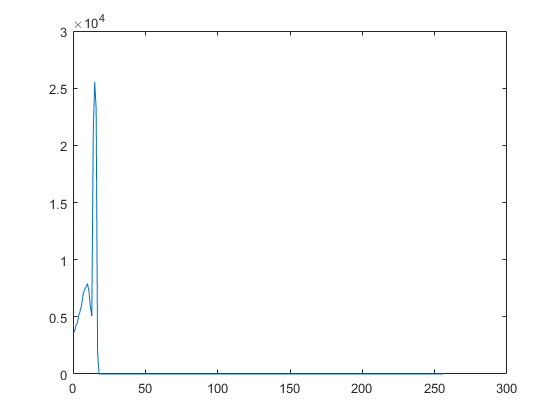


for i = 1:files
    for j = 1:cols
        h(im(i,j) + 1) = h(im(i,j) + 1) + 1;
    end
end

figure, plot(h)

### Construccion del histograma mediante función

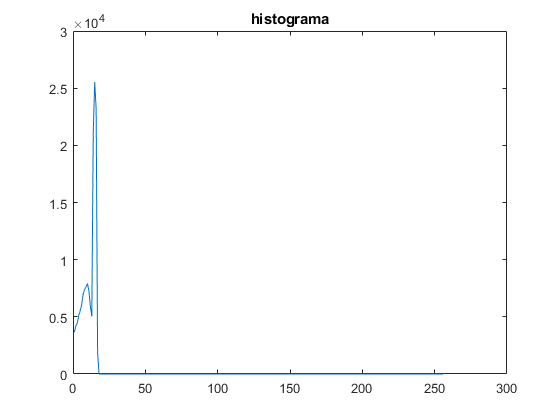

h = imhist(im);
figure, plot(h), title('histograma')

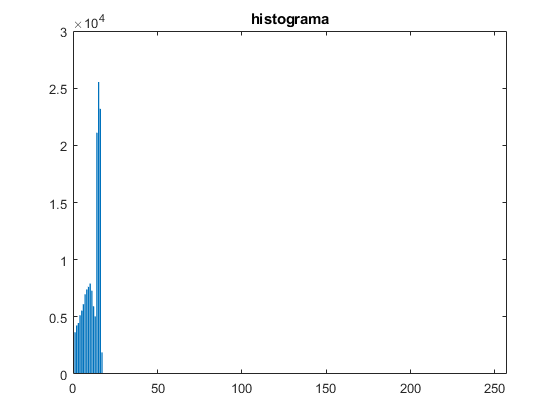


figure, bar(h), title('histograma')

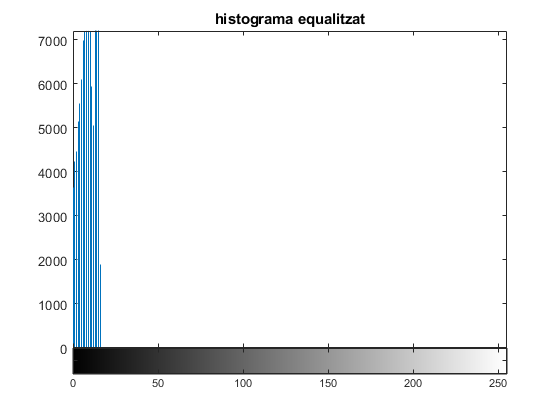


figure, imhist(im), title('histograma equalitzat')

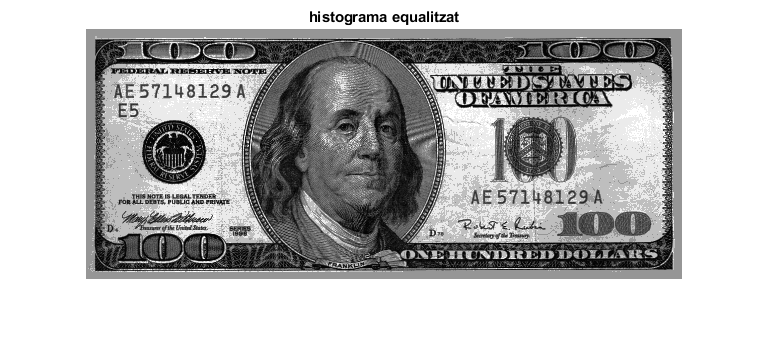


figure, histeq(im), title('histograma equalitzat')

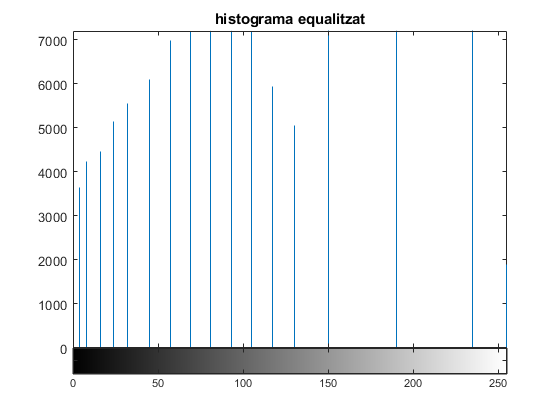


im3 = histeq(im);
figure, imhist(im3), title('histograma equalitzat')

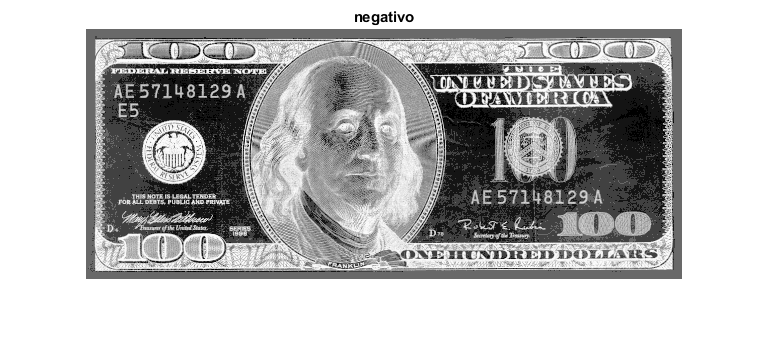


im4 = 255 - im3;
figure, imshow(im4), title('negativo')

### Transformaciones

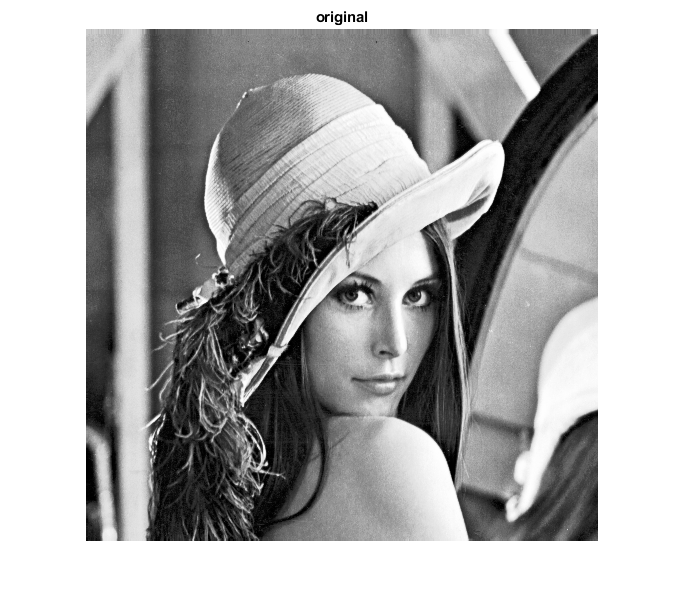

im = imread('lenna.tif');
figure, imshow(im), title('original')

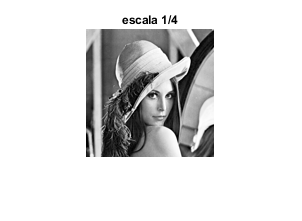


im2 = imresize(im, 0.25);
figure, imshow(im2), title('escala 1/4')

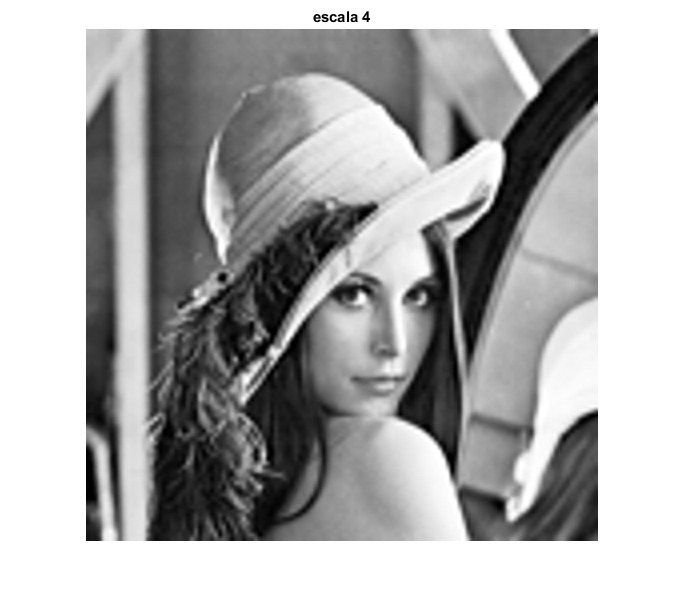


im3 = imresize(im2, 4);
figure, imshow(im3), title('escala 4')

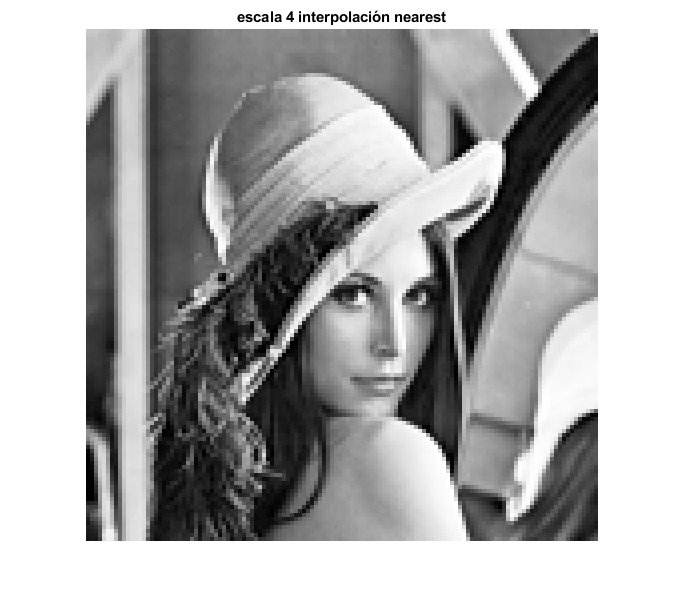


im4 = imresize(im2, 4, 'nearest');
figure, imshow(im4), title('escala 4 interpolación nearest')

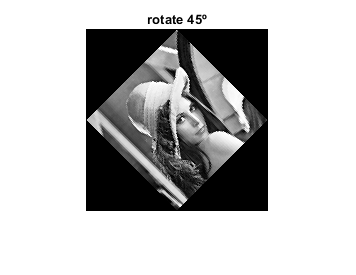


im5 = imrotate(im2, 45);
figure, imshow(im5), title('rotate 45º')


T = affine2d([1 0 0; 0.5 1 0; 0 0 1])

T =   affine2d with properties:

                 T: [3×3 double]
    Dimensionality: 2


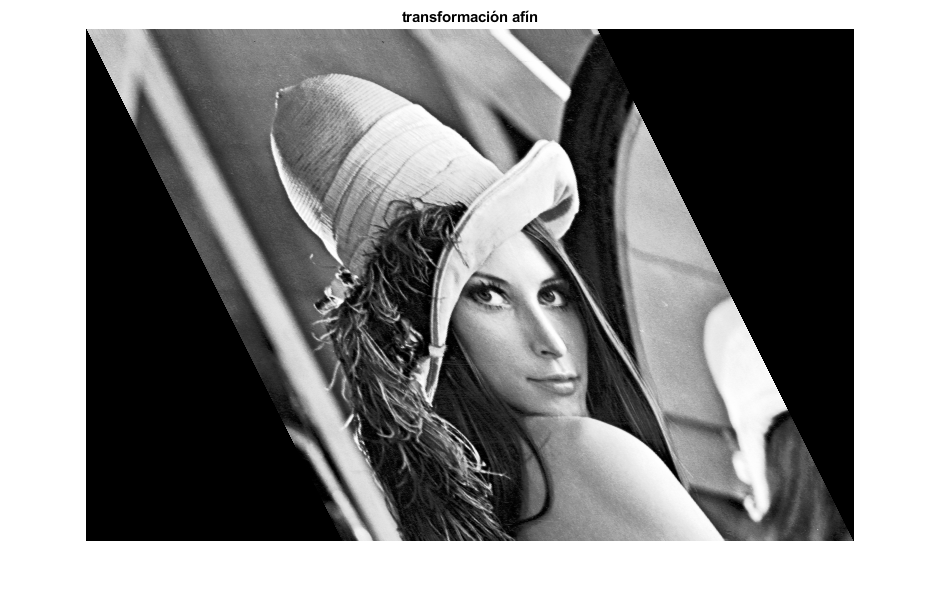

im6 = imwarp(im, T); % imwarp(...) aplica la transformación de T en im
figure, imshow(im6), title('transformación afín')


T2 = affine2d([1 0.75 0; 0.5 1 0; 0 0 1])

T2 =   affine2d with properties:

                 T: [3×3 double]
    Dimensionality: 2


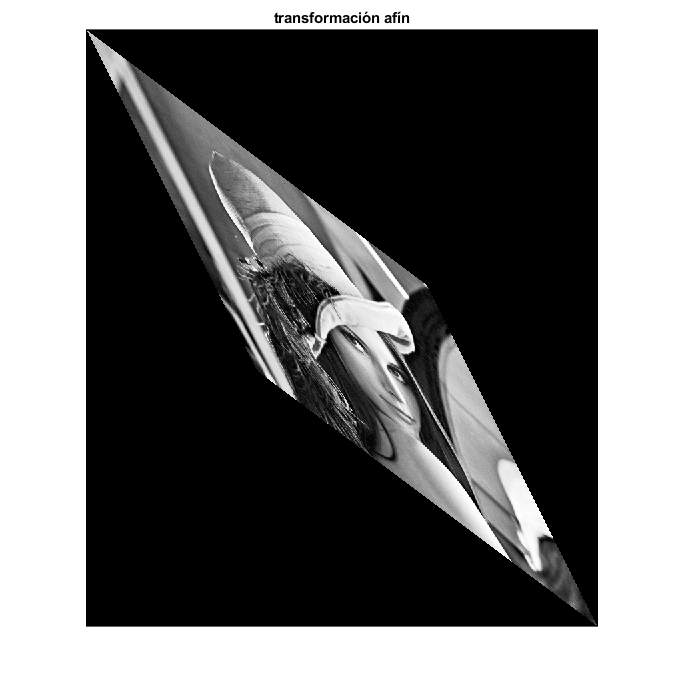

im7 = imwarp(im, T2); % imwarp(...) aplica la transformación de T en im
figure, imshow(im7), title('transformación afín')

### Detección por diferencia de imagenes

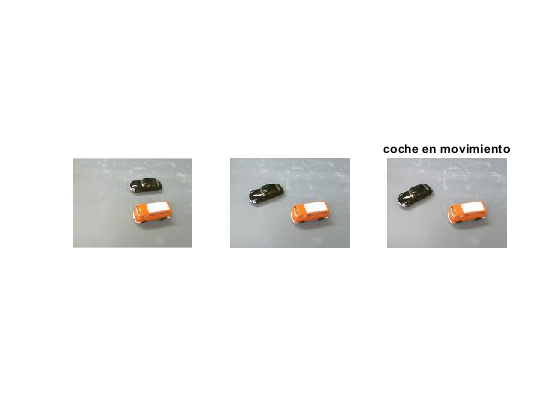

im1 = imread('toycars1.png');
im2 = imread('toycars2.png');
im3 = imread('toycars3.png');

figure
subplot(1, 3, 1), imshow(im1)
subplot(1, 3, 2), imshow(im2)
subplot(1, 3, 3), imshow(im3)
title('coche en movimiento')

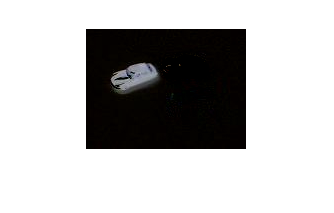


% Solución "mala" (no haciendo gestión de negativos)
res = im1 - im2;
figure, imshow(res)

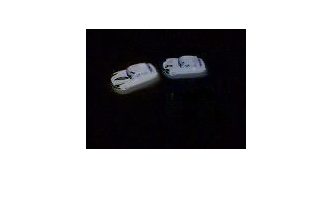


% Solución por diferencia absoluta/simétrica
res1 = imabsdiff(im1, im2);
figure, imshow(res1)

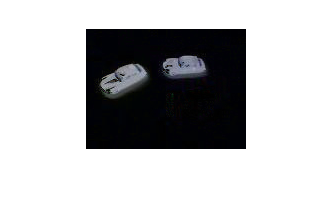


res2 = imabsdiff(im1, im3);
figure, imshow(res2)

### Producto de convoluciones

h = ones(3)

h =      1     1     1
     1     1     1
     1     1     1


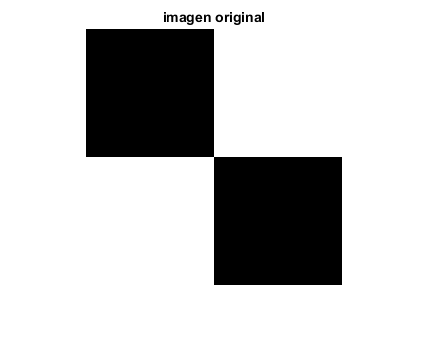


im = ones(256);
im(1:128, 1:128) = 0;
im(129:256, 129:256) = 0;
figure, imshow(im), title('imagen original')

res = zeros(256)

res =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

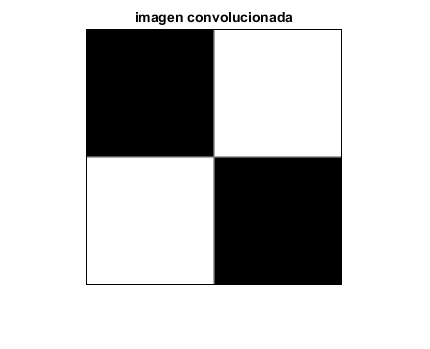


for i = 2:255
    for j = 2:255
        res(i, j) = h(1, 1)*im(i-1, j-1) + h(2, 1)*im(i, j-1) + h(1, 2)*im(i-1, j) + h(2, 2)*im(i, j) + h(3, 3)*im(i+1, j+1) + h(3, 2)*im(i+1, j) + h(2, 3)*im(i, j+1) + h(1, 3)*im(i-1, j+1) + h(3, 1)*im(i+1, j-1);
    end
end
res = res/9;

figure, imshow(res), title('imagen convolucionada')

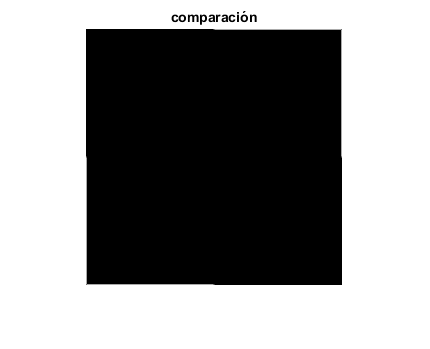


res2 = imfilter(im,h,'conv');
res2 = res2/9;

comp = res2 - res;
figure, imshow(comp)
title('comparación')